## EGN 495 - Load XBeach Output

Carolina Beach, NC

No Action - with 50-year SLR

Ashley Holsclaw

clear; clc;

Load XBeach Output from NetCDF File

x = ncread('xboutput.nc','globalx');
y = ncread('xboutput.nc','globaly');
zb = ncread('xboutput.nc','zb');
zs = ncread('xboutput.nc','zs');
H = ncread('xboutput.nc','H');
% H_mean = ncread('xboutput.nc','H_mean');
t = ncread('xboutput.nc','globaltime');

2D Bathymetric Map

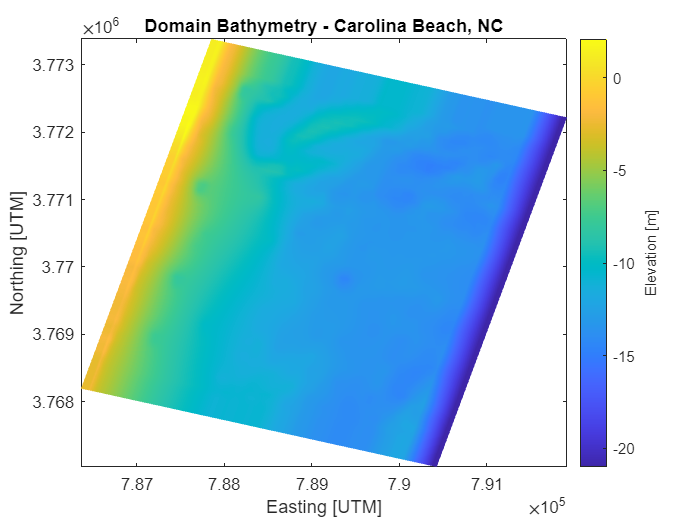

figure;
pcolor(x,y,zb(:,:,6))
colormap(parula)
shading interp
c = colorbar;
c.Label.String = 'Elevation [m]';
title('Domain Bathymetry - Carolina Beach, NC')
xlabel('Easting [UTM]')
ylabel('Northing [UTM]')

2D Wave Height Map (for a single time in the simulation)

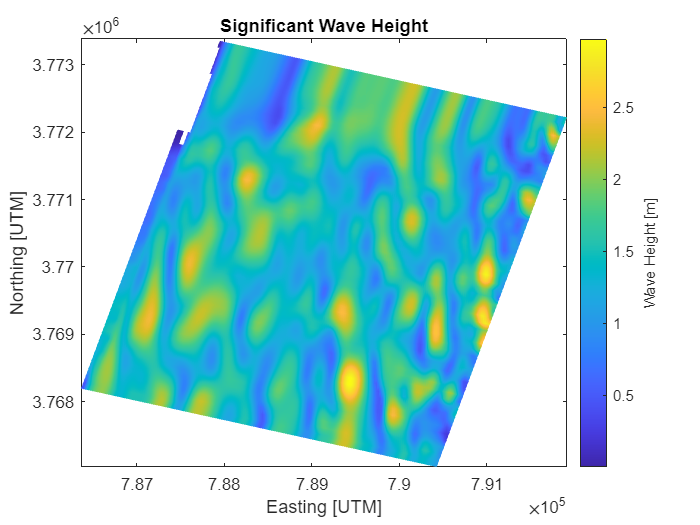

figure;
pcolor(x,y,H(:,:,6))
colormap(parula)
shading interp
c = colorbar;
c.Label.String = 'Wave Height [m]';
title('Significant Wave Height')
xlabel('Easting [UTM]')
ylabel('Northing [UTM]')

One Cross-shore Transect of Mean Wave Height Through the Center of your Model Domain (variable: H_mean)

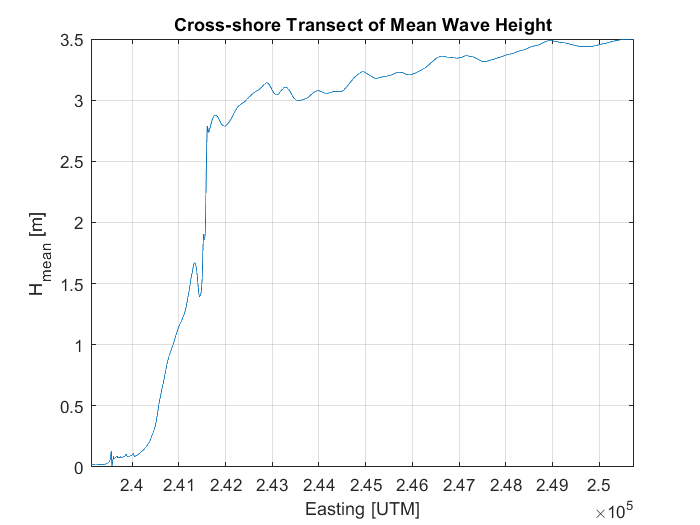

figure;
plot(x(:,round(size(x,2)/2)),H_mean(:,round(size(H_mean,2)/2)))
xlim([x(end,round(size(x,2)/2)) x(1,round(size(x,2)/2))])
title('Cross-shore Transect of Mean Wave Height')
xlabel('Easting [UTM]')
ylabel('H_m_e_a_n [m]')
grid on

Time Series of Wave Height at a Single Point in the Center of your Model Domain

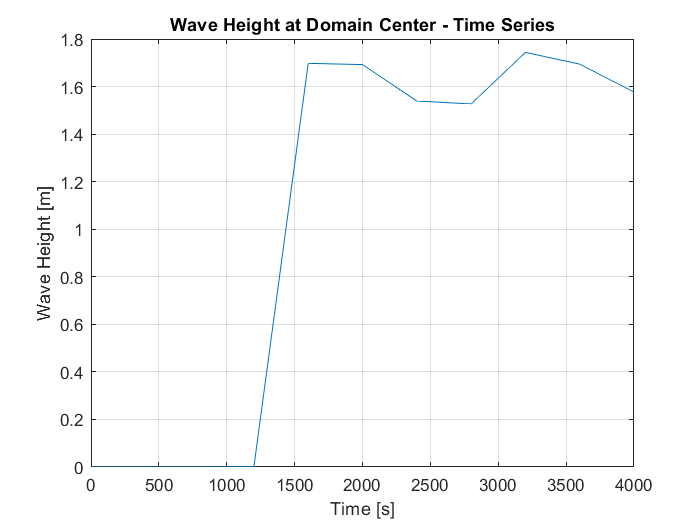

figure;
plot(t,squeeze(H(round(size(x,1)/2),round(size(x,2)/2),:)))
xlim([t(1) t(end)])
title('Wave Height at Domain Center - Time Series')
xlabel('Time [s]')
ylabel('Wave Height [m]')
grid on

Grid Resolution

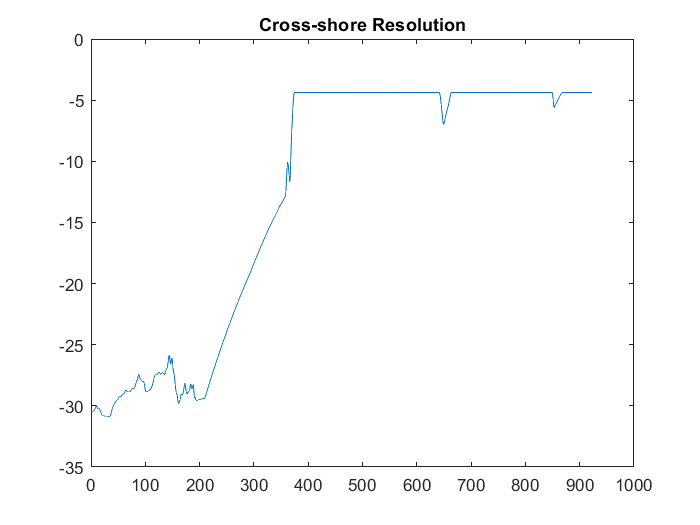

figure;
plot(gradient(x(:,round(size(x,2)/2))))
title('Cross-shore Resolution')

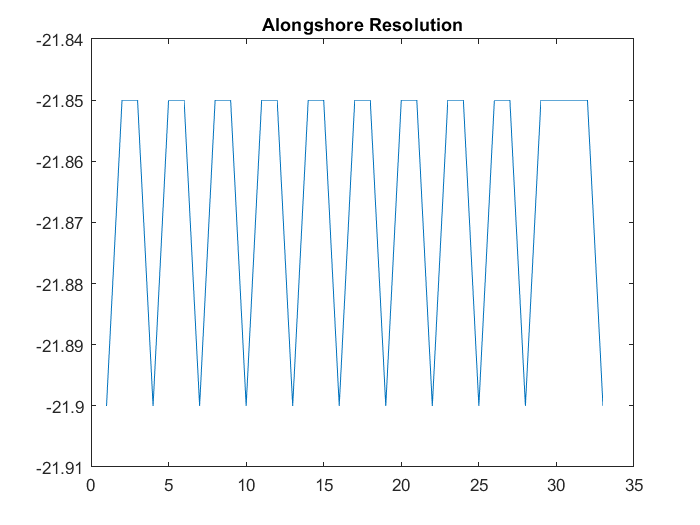

figure;
plot(gradient(y(round(size(y,1)/2),:)))
title('Alongshore Resolution')